Building surface for Center of Gravity ...


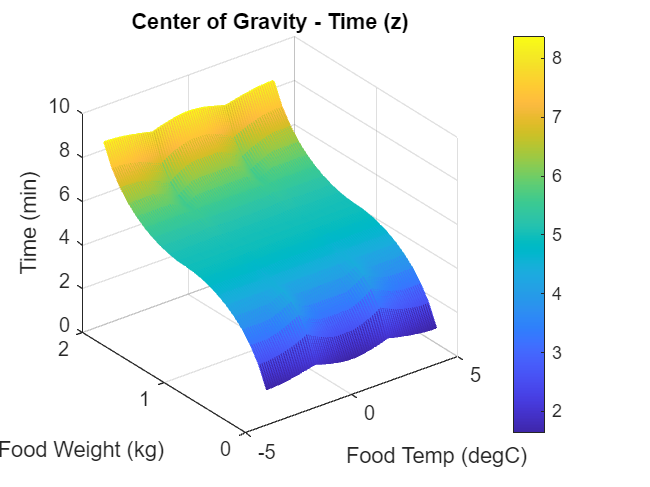

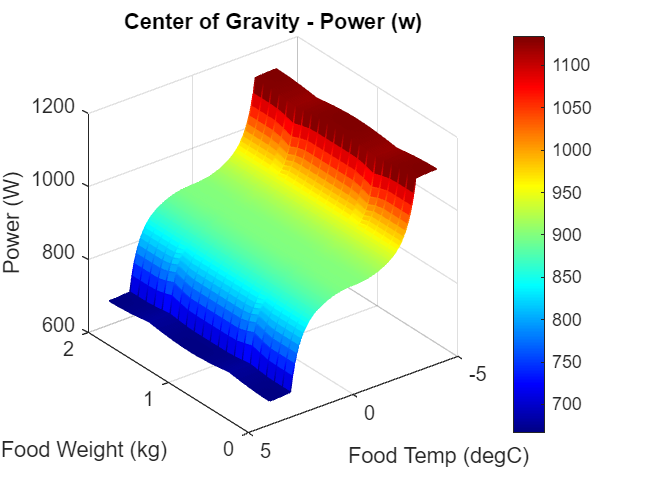

Building surface for Mean of Maxima ...


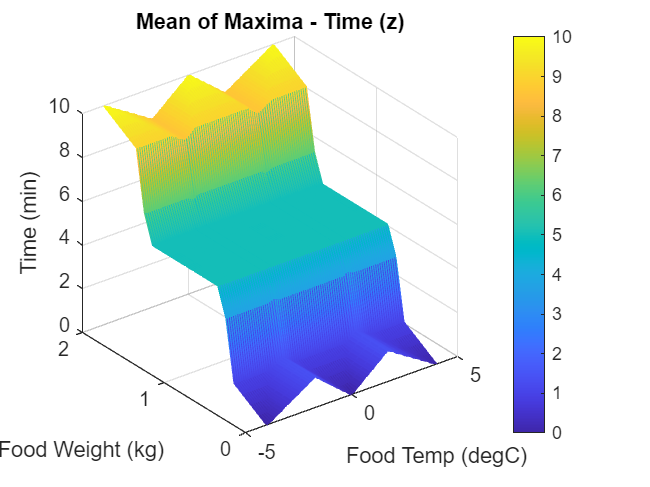

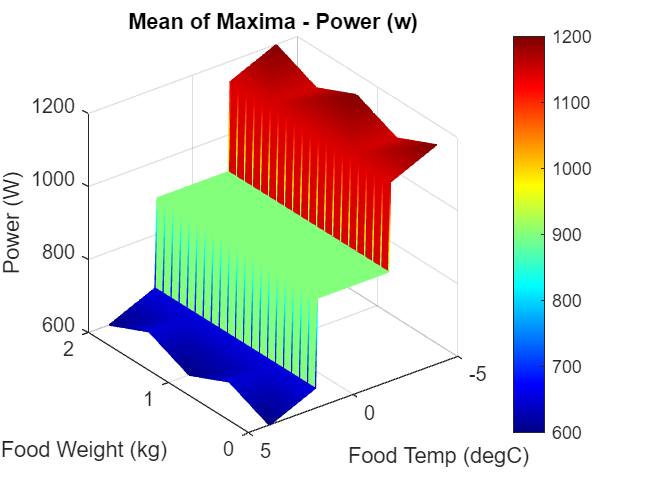

Building surface for Modified Mean of Maxima ...


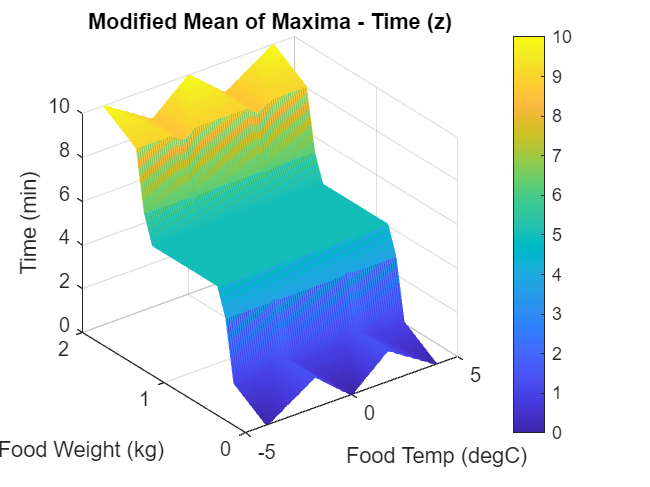

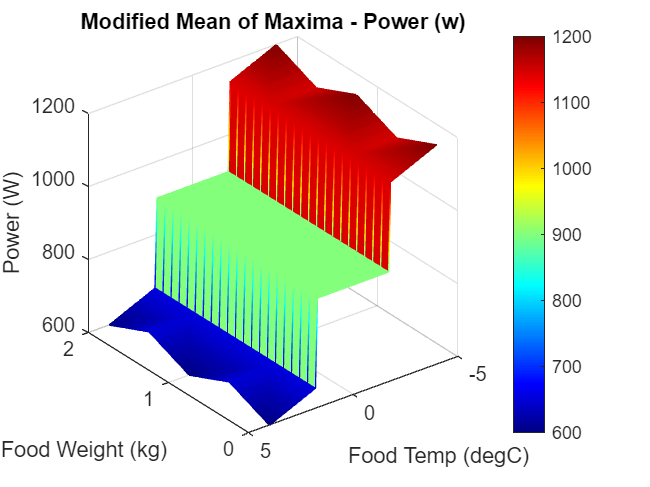

Building surface for Center Average ...


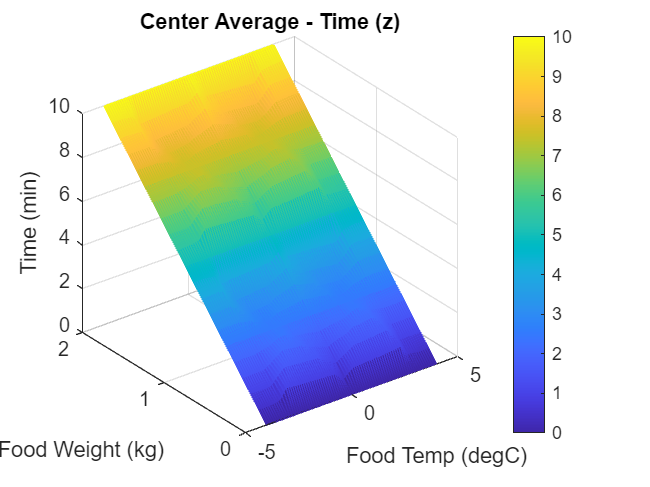

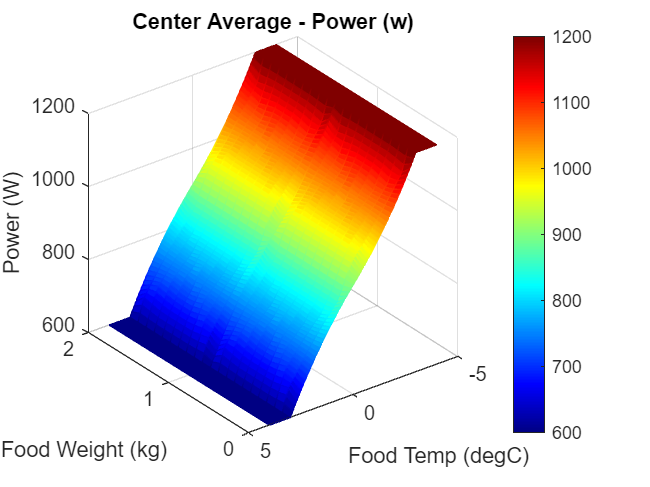

%% 1. 初始化與參數設定
clear; clc; close all;

% 建立輸出資料夾
output_dir = 'fuzzy_3d_outputs';
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

% 定義定義域 (Universe of discourse)
x_domain = -4:0.1:4;       % 溫度 x (°C)
y_domain = 0:0.1:2;        % 重量 y (kg)
z_domain = 0:0.1:10;       % 時間 z (min)
w_domain = 600:1:1200;     % 功率 w (W)

methods = {'cog', 'mom', 'modified_mom', 'center_average'};
method_titles = containers.Map({'cog', 'mom', 'modified_mom', 'center_average'}, ...
    {'Center of Gravity', 'Mean of Maxima', 'Modified Mean of Maxima', 'Center Average'});

%% 2. 建立推論表面並繪圖
for m = 1:length(methods)
    method = methods{m};
    fprintf('Building surface for %s ...\n', method_titles(method));
    
    % X 對應溫度 (x_domain)，Y 對應重量 (y_domain)
    [X, Y] = meshgrid(x_domain, y_domain); 
    Z_time = zeros(size(X));
    W_power = zeros(size(X));
    
    for i = 1:size(X, 1)
        for j = 1:size(X, 2)
            [z_val, w_val] = infer_one_point(X(i,j), Y(i,j), method, z_domain, w_domain);
            Z_time(i,j) = z_val;
            W_power(i,j) = w_val;
        end
    end
    
    % 繪製 Z (時間) 圖表 - 標準顯示
    plot_and_save(X, Y, Z_time, [method_titles(method) ' - Time (z)'], ...
        'Food Temp (degC)', 'Food Weight (kg)', 'Time (min)', ...
        fullfile(output_dir, ['z_' method '.png']), parula, false);

    % 繪製 W (功率) 圖表 - 反轉 X 軸 (讓溫度方向對調)
    plot_and_save(X, Y, W_power, [method_titles(method) ' - Power (w)'], ...
        'Food Temp (degC)', 'Food Weight (kg)', 'Power (W)', ...
        fullfile(output_dir, ['w_' method '.png']), jet, true);
end


fprintf('\n所有圖表已儲存至 %s\n', output_dir);


所有圖表已儲存至 fuzzy_3d_outputs



%% 3. 核心函數定義

function [z_out, w_out] = infer_one_point(x0, y0, method, z_domain, w_domain)
    mu_x = [left_shoulder(x0,-4,0), trimf(x0,-3,0,3), right_shoulder(x0,0,4)];
    mu_y = [left_shoulder(y0,0,1),  trimf(y0,0,1,2),  right_shoulder(y0,1,2)];
    
    alpha = [
        min(mu_x(1), mu_y(3)), min(mu_x(1), mu_y(2)), min(mu_x(1), mu_y(1)), ...
        min(mu_x(2), mu_y(3)), min(mu_x(2), mu_y(2)), min(mu_x(2), mu_y(1)), ...
        min(mu_x(3), mu_y(3)), min(mu_x(3), mu_y(2)), min(mu_x(3), mu_y(1))
    ];
    
    z_centers = [10, 5, 0, 10, 5, 0, 10, 5, 0];
    w_centers = [1200, 1200, 1200, 900, 900, 900, 600, 600, 600];

    if strcmp(method, 'center_average')
        denom = sum(alpha);
        if denom == 0, z_out = NaN; w_out = NaN; return; end
        z_out = sum(alpha .* z_centers) / denom;
        w_out = sum(alpha .* w_centers) / denom;
    else
        z_agg = zeros(size(z_domain));
        w_agg = zeros(size(w_domain));
        z_sets = {right_shoulder(z_domain,5,10), trimf(z_domain,0,5,10), left_shoulder(z_domain,0,5)};
        w_sets = {right_shoulder(w_domain,1000,1200), trimf(w_domain,600,900,1200), left_shoulder(w_domain,600,800)};
        z_idx = [1, 2, 3, 1, 2, 3, 1, 2, 3]; 
        w_idx = [1, 1, 1, 2, 2, 2, 3, 3, 3]; 

        for k = 1:9
            z_agg = max(z_agg, min(alpha(k), z_sets{z_idx(k)}));
            w_agg = max(w_agg, min(alpha(k), w_sets{w_idx(k)}));
        end
        z_out = defuzzify_alg(z_domain, z_agg, method);
        w_out = defuzzify_alg(w_domain, w_agg, method);
    end
end

function val = defuzzify_alg(domain, mu, method)
    if sum(mu) == 0, val = NaN; return; end
    switch method
        case 'cog'
            val = sum(domain .* mu) / sum(mu);
        case 'mom'
            max_mu = max(mu);
            max_idx = abs(mu - max_mu) < 1e-6;
            val = mean(domain(max_idx));
        case 'modified_mom'
            max_mu = max(mu);
            max_idx = find(abs(mu - max_mu) < 1e-6);
            val = (domain(max_idx(1)) + domain(max_idx(end))) / 2;
    end
end

function mu = trimf(x, a, b, c)
    mu = max(min((x-a)/(b-a), (c-x)/(c-b)), 0);
    mu(x==b) = 1;
end

function mu = left_shoulder(x, a, b)
    mu = ones(size(x));
    mu(x > a & x < b) = (b - x(x > a & x < b)) / (b - a);
    mu(x >= b) = 0;
end

function mu = right_shoulder(x, a, b)
    mu = zeros(size(x));
    mu(x > a & x < b) = (x(x > a & x < b) - a) / (b - a);
    mu(x >= b) = 1;
end

function plot_and_save(X, Y, Z, titl, xl, yl, zl, path, cmap, reverseX)
    figure('Color', [1 1 1]); 
    surf(X, Y, Z, 'EdgeColor', 'interp'); 
    colormap(cmap); colorbar;
    title(titl); xlabel(xl); ylabel(yl); zlabel(zl);
    view([-37.5, 30]); % 設置觀察視角
    grid on;
    if reverseX
        set(gca, 'XDir', 'reverse'); % 這裡將 X 軸 (溫度) 對調
    end
    saveas(gcf, path);
end